### Preparation

clear
close all

support.fcn_download_img

kodim01.png already exists in ./data/
kodim02.png already exists in ./data/
kodim03.png already exists in ./data/
kodim04.png already exists in ./data/
kodim05.png already exists in ./data/
kodim06.png already exists in ./data/
kodim07.png already exists in ./data/
kodim08.png already exists in ./data/
kodim09.png already exists in ./data/
kodim10.png already exists in ./data/
kodim11.png already exists in ./data/
kodim12.png already exists in ./data/
kodim13.png already exists in ./data/
kodim14.png already exists in ./data/
kodim15.png already exists in ./data/
kodim16.png already exists in ./data/
kodim17.png already exists in ./data/
kodim18.png already exists in ./data/
kodim19.png already exists in ./data/
kodim20.png already exists in ./data/
kodim21.png already exists in ./data/
kodim22.png already exists in ./data/
kodim23.png already exists in ./data/
kodim24.png already exists in ./data/
See <a href="http://www.r0k.us/graphics/kodak/">Kodak Lossless True Color Image Suite</a

### Parameter settings

- sgm: Standard deviation of noise $\sigma_w$ 

- nlevels: # of Tree levels

Let $R_M^P(\tau)$ be the redundancy of $\tau$-level tree-structured filter bank, then we have the relation 

    
$$R_M^P(\tau)=\left\{\begin{array}{ll} (P-1)\tau + 1, & M=1, \\ \frac{P-1}{M-1}-\frac{P-M}{(M-1)M^\tau}, & M\geq 2.\end{array}\right.$$


% Check initial state
checkInitialState = false

checkInitialState = logical
   0



% Number of iterations
nIters = 5;


% Decimation factor (Strides)
decFactor = [1 1] * 2 % [My Mx]

decFactor =      2     2



% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [1 1] * 8% [Ps Pa] (Ps=Pa)

nChannels =      8     8


% Number of tree levels
nLevels = 4

nLevels = 4


% No DC-leakage
noDcLeakage = true

noDcLeakage = logical
   1



% Redundancy
P = sum(nChannels);
M = prod(decFactor);
redundancy = ...
    (prod(decFactor)==1)*((P-1)*nLevels+1) + ...
    (prod(decFactor)>1)*((P-1)/(M-1)-(P-M)/((M-1)*M^nLevels))

redundancy = 4.9844


% Polyphase Order
ppOrder = [1 1] *4

ppOrder =      4     4


% Parameter settins for LET
sigma =  10^-4

sigma = 1.0000e-04

isLET = true

isLET = logical
   1



% Parameter settings for soft-thresholding
lambda = 10^-1% -0.1

lambda = 0.1000


% Std of noise 
sgmuint8 = 20;
sgm = sgmuint8/255;

% Number of patchs per image
nSubImgs = 128;

% Patch size for training
szPatchTrn = [64 64 3]; % > [ (Ny+1)My (Nx+1)Mx ]

% Standard deviation of initial angles
stdInitAng = pi/6;

% Initial learning rate
initialLearnRate = 10^-2

initialLearnRate = 0.0100


% Learn rate factors (Set factor to 0 for frozen parameters)
factor4angles = 1; % NSOLT
factor4lambda = 1; % Soft-Th.
factor4sigma = 1; % LET
factor4a1 = 1; % LET
factor4a2 = 1; % LET
factor4b1 = 1; % LET
factor4b2 = 1; % LET
factor4gamma = 1; % Step-size

% L2 factors
l2factor4angles = 1; % NSOLT
l2factor4lambda = 1; % Soft-Th.
l2factor4sigma = 1; % LET
l2factor4gamma = 1; % Step-size

% Mini batch size
miniBatchSize = 32;

% Number of Epochs (1 Epoch = nSubImgs/miniBachSize iterlations)
maxEpochs = 16;

if checkInitialState
    maxEpochs = 1;
end

% Number of iterations
maxIters = nSubImgs/miniBatchSize * maxEpochs

maxIters = 64

## Read image

u = im2double(imread('./data/kodim01.png'));


## Observed image

- 
$$\mathbf{v}=\mathbf{Pu}+\mathbf{w}$$


- 
$$\mathbf{w}\sim\mathrm{Norm}\left(\mathbf{w}|\mathbf{\mu}_w=\mathbf{0},\sigma_w^2\mathbf{I}\right)$$


## Measurement Process

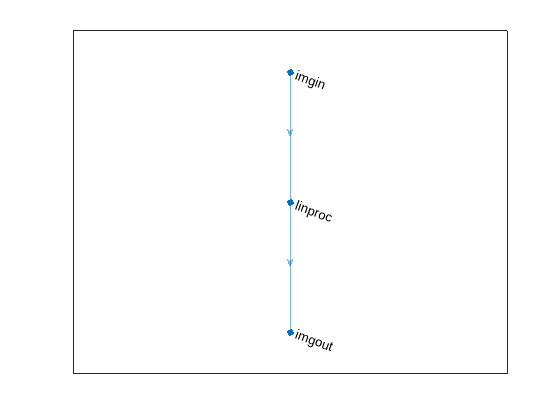

hsize = [9 9];
hsigma = 2;
downfactor = [2 2];
padopt = 'circ';
fwdproclayer = forwardMeasurement2dLayer(...
    'Name','linproc',...
    'Sigma',hsigma,...
    'PsfSize',hsize,...
    'PadOption',padopt,...
    'DecimationFactor',downfactor);
adjproclayer = fwdproclayer.createAdjointLayer();

% Simulation 
proclgraph = layerGraph();
proclgraph = proclgraph.addLayers([ ...
    imageInputLayer(size(u),'Name','imgin','Normalization','none'),...
    fwdproclayer,...
    regressionLayer('Name','imgout')]);
plot(proclgraph)

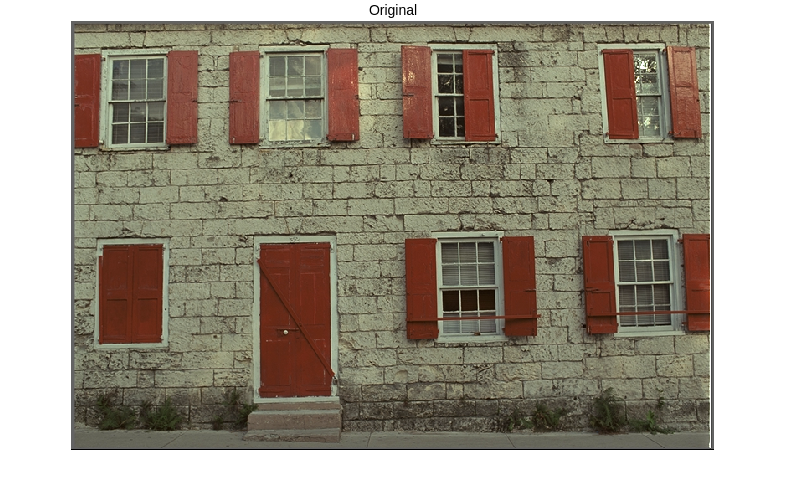

procnet = assembleNetwork(proclgraph);
v = imnoise(procnet.predict(u),'gaussian',0,sgm^2);

%
imshow(u)
title('Original')

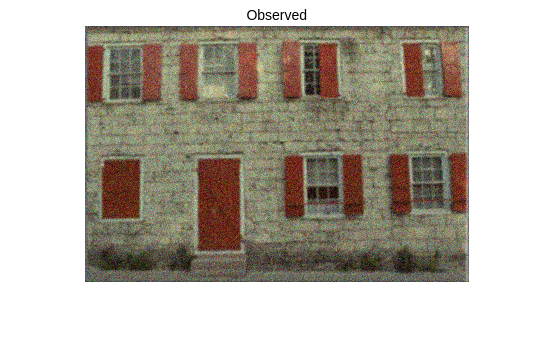

imshow(v)
title('Observed')

### Learned ISTA with Structured Convolutional Dictionary

#### References

- K. Gregor and Y. LeCun, "Learning fast approximations of sparse coding", *Proc. Int. Conf. Machine Learning*, pp. 399-406, 2010.

- V. Monga, Y. Li and Y. C. Eldar, "Algorithm Unrolling: Interpretable, Efficient Deep Learning for Signal and Image Processing," in IEEE Signal Processing Magazine, vol. 38, no. 2, pp. 18-44, March 2021, doi: 10.1109/MSP.2020.3016905.

- MATLAB SaivDr Package: [https://github.com/msiplab/SaivDr](https://github.com/msiplab/SaivDr)

- S. Muramatsu, K. Furuya and N. Yuki, "Multidimensional Nonseparable Oversampled Lapped Transforms: Theory and Design," in IEEE Transactions on Signal Processing, vol. 65, no. 5, pp. 1251-1264, 1 March1, 2017, doi: 10.1109/TSP.2016.2633240.

- S. Muramatsu, T. Kobayashi, M. Hiki and H. Kikuchi, "Boundary Operation of 2-D Nonseparable Linear-Phase Paraunitary Filter Banks," in IEEE Transactions on Image Processing, vol. 21, no. 4, pp. 2314-2318, April 2012, doi: 10.1109/TIP.2011.2181527.

- S. Muramatsu, M. Ishii and Z. Chen, "Efficient parameter optimization for example-based design of nonseparable oversampled lapped transform," 2016 IEEE International Conference on Image Processing (ICIP), Phoenix, AZ, 2016, pp. 3618-3622, doi: 10.1109/ICIP.2016.7533034.

- Furuya, K., Hara, S., Seino, K., & Muramatsu, S. (2016). Boundary operation of 2D non-separable oversampled lapped transforms. *APSIPA Transactions on Signal and Information Processing, 5*, E9. doi:10.1017/ATSIP.2016.3.

#### Problem setting:

    
$$\{\hat{\mathbf{\theta}},\{ \hat{\mathbf{s}}_n \}\}=\arg\min_{\{\mathbf{\theta},\{\mathbf{s}_n\}\}}\frac{1}{2S}\sum_{n=1}^{S}\left(\|\mathbf{v}_n-\mathbf{D}_{\mathbf{\theta}}\hat{\mathbf{s}}_n\|_2^2,\ +\lambda\|\mathbf{s}_n\|_1\right),$$$


where $\mathbf{D}_{\mathbf{\theta}}$ is a dictionary with the design parameter vector $\mathbf{\theta}}$.

#### ISTA

- Initialization: $\mathbf{s}^{(0)}$, $t\leftarrow 0$

- Proximal gradient descent: $\mathbf{s}^{(t+1)}\leftarrow \mathcal{T}_{\gamma \lambda}\left( \mathbf{s}^{(t)}-\gamma\nabla_\mathbf{s}f(\mathbf{s}^{(t)})\right)$

- If a stopping critera is satisfied then finish, otherwise $t\rightarrow t+1$ and go to Step 2.

where

- 
$$\nabla_\mathbf{s}f(\mathbf{s})=\mathbf{D}_{\mathbf{\theta}}^T\mathbf{P}^T(\mathbf{PD_{\mathbf{\theta}}\mathbf{s}-\mathbf{v})$$


- 
$$\mathcal{T}_{\gamma\lambda}(\mathbf{s})=\mathrm{sign}(\mathbf{s})\odot\max(\mathrm{abs}(\mathbf{s})-\gamma\lambda\mathbf{1},\mathbf{0})$$


- $\gamma<2/\beta$: Step size

- $\beta$: Lipschitz constant of $\nabla f$, where $\beta = (\sigma_{\mathrm{max}}(\mathbf{PD}))^2$

Step 2 of the ISTA can be written as follows

- 
$$\mathbf{s}^{(t+1)}\leftarrow \mathcal{T}_{\gamma g}\left(\mathbf{s}^{(t)}-\gamma\mathbf{D}_{\mathbf{\theta}}^T\mathbf{P}^T(\mathbf{PD}_{\mathbf{\theta}}\mathbf{s}^{(t)}-\mathbf{v})\right)$$


The above steps can equivalently be rewritten as a form of analysis, thresholding, and synthesis as follows.

#### Analysis-synthesis view of ISTA 

- Initialization: $\mathbf{s}^{(0)}$, $\mathbf{u}^{(0)}\leftarrow \mathbf{D}_{\mathbf{\theta}}\mathbf{s}^{(0)}$, $t\leftarrow 0$

- Residual: $\mathbf{r}^{(t)}\leftarrow \mathbf{P}^T(\mathbf{P}\mathbf{u}^{(t)}-\mathbf{v})$

- Analysis process: $\mathbf{y}^{(t)}\leftarrow \mathbf{D}_{\mathbf{\theta}}^T\mathbf{r}^{(t)}$

- Proximal gradient descent: $\mathbf{s}^{(t+1)}\leftarrow \mathcal{T}_{\gamma \lambda}\left(\mathbf{s}^{(t)}-\gamma\mathbf{y}^{(t)}\right)$

- Synthesis process: $\mathbf{u}^{(t+1)}\leftarrow \mathbf{D}_{\mathbf{\theta}}\mathbf{s}^{(t+1)}$

- If a stopping critera is satisfied then finish, otherwise $t\rightarrow t+1$ and go to Step 2.

The initialization part is set as

- 
$$\mathbf{s}^{(0)}\leftarrow \mathbf{D}^T_{\mathbf{\theta}}\mathbf{P}^T\mathbf{v}\Rightarrow\mathbf{u}^{(0)}\leftarrow \mathbf{P}^T\mathbf{v}$$


## Construction of layers

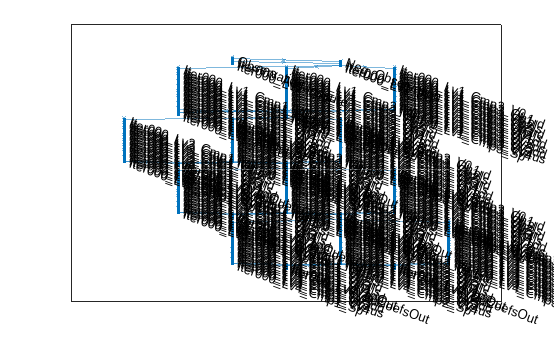

import saivdr.dcnn.*
nComponents = szPatchTrn(3);

% Parameter settings for step size
H = fftn(fwdproclayer.psf,2.^nextpow2([size(u,1) size(u,2)]));
beta = max(abs(H(:)).^2); % λmax(PP.')
gamma = 2./(beta+1e-2);

% Initialize
strIter = sprintf('Iter%03d_',0);
listalgraph = fcn_creatensoltlgraph2d([],...
    'AppendInOutLayers',false,...
    'NumberOfComponents',nComponents,...
    'NumberOfChannels',nChannels,...
    'DecimationFactor',decFactor,...
    'PolyPhaseOrder',ppOrder,...
    'NumberOfLevels',nLevels,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Analyzer',...
    'Prefix',strIter);
imginputlayer0 = imageInputLayer(szPatchTrn./[downfactor 1],'Name','Observation','Normalization','none');
adjproclayer0 = adjproclayer;
adjproclayer0.Name = [strIter 'AdjMeasure'];
listalgraph = listalgraph.addLayers(...
    [imginputlayer0,adjproclayer0]);
%
strLv = sprintf('Lv%0d_',1);
listalgraph = listalgraph.connectLayers([strIter 'AdjMeasure'],[strIter strLv 'In']);

% Add intermediate result output
listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'Out']));
listalgraph = listalgraph.connectLayers([strIter 'AdjMeasure'],[strIter strLv 'Out']);

% Add Coefs. output
strLv = sprintf('Lv%0d_',nLevels);
listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'DcCoefsOut']));
listalgraph = listalgraph.connectLayers([strIter strLv 'DcOut'],[strIter strLv 'DcCoefsOut']);
for iLv = nLevels:-1:1
    strLv = sprintf('Lv%0d_',iLv);
    listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'AcCoefsOut']));
    listalgraph = listalgraph.connectLayers([strIter strLv 'AcOut'],[strIter strLv 'AcCoefsOut']);
end

% Add negative process
listalgraph = listalgraph.addLayers(negativeLayer('Name','Neg_Observation'));
listalgraph = listalgraph.connectLayers('Observation','Neg_Observation');

% Plot
plot(listalgraph)

import saivdr.dcnn.*
nComponents = szPatchTrn(3);
% Iteration
for iter = 1:nIters
    strIter = sprintf('Iter%03d_',iter);
    strIterPre = sprintf('Iter%03d_',iter-1);
    
    % Analysis-synthesis system
    listalgraph = fcn_creatensoltlgraph2d(listalgraph,...    
        'AppendInOutLayers',false,...
        'NumberOfComponents',nComponents,...
        'NumberOfChannels',nChannels,...
        'DecimationFactor',decFactor,...
        'PolyPhaseOrder',ppOrder,...
        'NumberOfLevels',nLevels,...
        'NumberOfVanishingMoments',noDcLeakage,...
        'Prefix',strIter);

    % Measurement processes
    fwdproclayeri = fwdproclayer;
    fwdproclayeri.Name = [strIter 'FwdMeasure'];
    adjproclayeri = adjproclayer;
    adjproclayeri.Name = [strIter 'AdjMeasure'];
    listalgraph = listalgraph.addLayers([fwdproclayeri,additionLayer(2,'Name',[strIter 'Residual']),adjproclayeri]);
    listalgraph = listalgraph.connectLayers([strIter 'AdjMeasure'],[strIter 'Lv1_In']);

    % Analyzer
    strLv = sprintf('Lv%0d_',1);
    listalgraph = listalgraph.replaceLayer([strIter strLv 'In'],...
        learnableScalingLayer('Name',[strIter strLv 'In'],'Scale',-gamma));

    % For DC
    strLv = sprintf('Lv%0d_',nLevels);
    listalgraph = listalgraph.disconnectLayers([strIter strLv 'DcOut'],[strIter strLv 'DcIn']);
    listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'DcCoefsIn']));
    listalgraph = listalgraph.addLayers(additionLayer(2,'Name',[strIter strLv 'DcCoefsResidual']));
    listalgraph = listalgraph.connectLayers([strIter strLv 'DcOut'],[strIter strLv 'DcCoefsResidual/in1']);
    listalgraph = listalgraph.connectLayers([strIter strLv 'DcCoefsIn'],[strIter strLv 'DcCoefsResidual/in2']);
    listalgraph = listalgraph.connectLayers([strIter strLv 'DcCoefsResidual'],[strIter strLv 'DcIn']);
    % For AC
    for iLv = nLevels:-1:1
        strLv = sprintf('Lv%0d_',iLv);
        listalgraph = listalgraph.disconnectLayers([strIter strLv 'AcOut'],[strIter strLv 'AcIn']);
        listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'AcCoefsIn']));
        listalgraph = listalgraph.addLayers(additionLayer(2,'Name',[strIter strLv 'AcCoefsResidual']));
        listalgraph = listalgraph.connectLayers([strIter strLv 'AcOut'],[strIter strLv 'AcCoefsResidual/in1']);
        listalgraph = listalgraph.connectLayers([strIter strLv 'AcCoefsIn'],[strIter strLv 'AcCoefsResidual/in2']);
    end

    % Synthesizer
    strLvPre = '';
    % For DC
    strLv = sprintf('Lv%0d_',nLevels);
    if iter < nIters
        listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'DcCoefsOut']));
        listalgraph = listalgraph.connectLayers([strIter strLv 'DcCoefsResidual'],[strIter strLv 'DcCoefsOut']);
    end
    % For AC
    for iLv = nLevels:-1:1
        strLv = sprintf('Lv%0d_',iLv);
        % For AC
        if isLET
            if iLv == nLevels
                listalgraph = listalgraph.addLayers(...
                    letLayer('Name',[strIter strLv 'AcTh'],'Sigma',sigma,... % Activation function for AC between Analyzer & Synthesizer
                    'IsInterScale',false,...
                    'NumberOfChannels',nComponents*(sum(nChannels)-1)));
                listalgraph = listalgraph.connectLayers([strIter strLv 'AcCoefsResidual'],[strIter strLv 'AcTh']);
            else
                listalgraph = listalgraph.addLayers(...
                    letLayer('Name',[strIter strLv 'AcTh'],'Sigma',sigma,... % Activation function for AC between Analyzer & Synthesizer
                    'IsInterScale',true,...
                    'NumberOfChannels',nComponents*(sum(nChannels)-1)));
                listalgraph = listalgraph.connectLayers([strIter strLvPre 'AcTh'],[strIter strLv 'AcTh/parent']);
                listalgraph = listalgraph.connectLayers([strIter strLv 'AcCoefsResidual'],[strIter strLv 'AcTh/child']);
            end
        else % Soft-thresholding
            listalgraph = listalgraph.addLayers(...
                sfthLayer('Name',[strIter strLv 'AcTh'],'Lambda',lambda,... % Activation function for AC between Analyzer & Synthesizer
                'NumberOfChannels',nComponents*(sum(nChannels)-1)));
            listalgraph = listalgraph.connectLayers([strIter strLv 'AcCoefsResidual'],[strIter strLv 'AcTh']);
        end
        listalgraph = listalgraph.connectLayers([strIter strLv 'AcTh'],[strIter strLv 'AcIn']);
        %
        if iter < nIters
            listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'AcCoefsOut']));
            listalgraph = listalgraph.connectLayers([strIter strLv 'AcTh'],[strIter strLv 'AcCoefsOut']);
        end
        %
        strLvPre = strLv;
    end
    
    % Connect iteration stages
    listalgraph = listalgraph.connectLayers([strIterPre 'Lv1_Out'],[strIter 'FwdMeasure']);
    listalgraph = listalgraph.connectLayers('Neg_Observation',[strIter 'Residual/in2']);
    %
    strLv = sprintf('Lv%0d_',nLevels);
    listalgraph = listalgraph.connectLayers([strIterPre strLv 'DcCoefsOut'],[strIter strLv 'DcCoefsIn']);
    for iLv = nLevels:-1:1
        strLv = sprintf('Lv%0d_',iLv);
        listalgraph = listalgraph.connectLayers([strIterPre strLv 'AcCoefsOut'],[strIter strLv 'AcCoefsIn']);
    end
end
%plot(listalgraph)

% Output
strIter = sprintf('Iter%03d_',nIters);
listalgraph = listalgraph.addLayers(regressionLayer('Name','Restoration'));
listalgraph = listalgraph.connectLayers([strIter 'Lv1_Out'],'Restoration');

% Check
analyzeNetwork(listalgraph);

### Preparation of traning image

Randomly extracting patches from the image data store

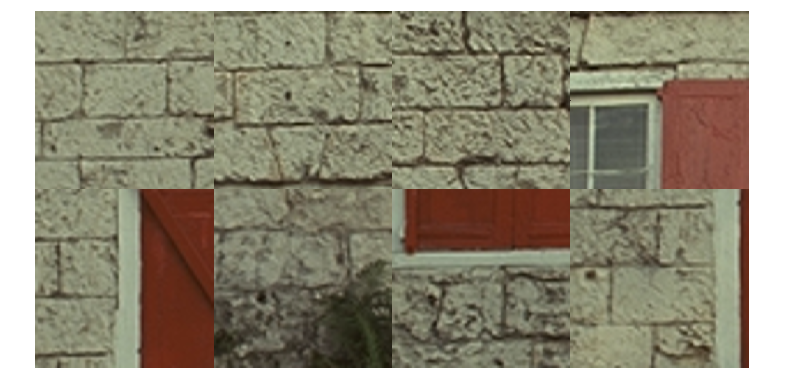

imds = imageDatastore("./data/kodim01.png","ReadFcn",@(x) im2single(imread(x)));
patchds = randomPatchExtractionDatastore(imds,imds,szPatchTrn,'PatchesPerImage',nSubImgs);
minibatch = preview(patchds);
responses = minibatch.ResponseImage;
montage(responses,'Size',[2 4]);

## Preperation of data set

proclgraph = layerGraph();
proclgraph = proclgraph.addLayers([ ...
    imageInputLayer(szPatchTrn./[downfactor 1],'Name','imgin','Normalization','none'),...
    fwdproclayer]);
procnet = dlnetwork(proclgraph);
obsds = transform(patchds, @(x) myobservation(x,procnet,sgm));

## Training options

opts = trainingOptions('sgdm', ... % Stochastic gradient descent w/ momentum
    ...'Momentum', 0.9000,...
    'InitialLearnRate',initialLearnRate,...
    ...'LearnRateScheduleSettings','none',...
    'L2Regularization',0.0,...1.0000e-04,... % Set zero since parameters are rotaion angles.
    ...'GradientThresholdMethod','l2norm',...
    ...'GradientThreshold',Inf,...
    'MaxEpochs',maxEpochs,...30,...
    'MiniBatchSize',miniBatchSize,...128,...
    'Verbose',1,...
    'VerboseFrequency',32,...50,...
    ...'ValidationData',[],...
    ...'ValidationFrequency',50,...
    ...'ValidationPatience',Inf,...
    ...'Shuffle','once',...
    ...'CheckpointPath','',...
    ...'ExecutionEnvironment','auto',...
    ...'WorkerLoad',[],...
    ...'OutputFcn',[],...
    'Plots','training-progress',...
    ...'SequenceLength','longest',...
    ...'SequencePaddingValue',0,...
    ...'SequencePaddingDirection','right',...
    ...'DispatchInBackground',0,...
    'ResetInputNormalization',0);...1

## Parameter initialization

listalgraph = listalgraph.removeLayers('Restoration');
listanet = dlnetwork(listalgraph);

% Initialize parameters
nLearnables = height(listanet.Learnables);
for iLearnable = 1:nLearnables
    if listanet.Learnables.Parameter(iLearnable)=="Angles"
        layerName = listanet.Learnables.Layer(iLearnable);
        listanet.Learnables.Value(iLearnable) = ...
            cellfun(@(x) x+stdInitAng*randn(size(x)), ...
            listanet.Learnables.Value(iLearnable),'UniformOutput',false);
    end
end

% Set learn rate factor & L2 factor
 for iLearnable = 1:nLearnables
     layerName = listanet.Learnables.Layer(iLearnable);
     parameterName = listanet.Learnables.Parameter(iLearnable);
     if parameterName == "Angles"
         listanet = listanet.setLearnRateFactor(layerName,"Angles",factor4angles);
         listanet = listanet.setL2Factor(layerName,"Angles",l2factor4angles);
     elseif parameterName == "Sigma"
         listanet = listanet.setLearnRateFactor(layerName,"Sigma",factor4sigma);
         listanet = listanet.setL2Factor(layerName,"Sigma",l2factor4sigma);
     elseif parameterName == "Lambda"
         listanet = listanet.setLearnRateFactor(layerName,"Lambda",factor4lambda);
         listanet = listanet.setL2Factor(layerName,"Lambda",l2factor4lambda);
     elseif ~isempty(regexp(layerName,'^Iter\d+_Lv\d+_In$','once')) && parameterName == "Scale" % gamma
         listanet = listanet.setLearnRateFactor(layerName,"Scale",factor4gamma);
         listanet = listanet.setL2Factor(layerName,"Scale",l2factor4gamma);
     elseif parameterName == "a1"
         listanet = listanet.setLearnRateFactor(layerName,"a1",factor4a1);
     elseif parameterName == "a2"
         listanet = listanet.setLearnRateFactor(layerName,"a2",factor4a2);
     elseif parameterName == "b1"
         listanet = listanet.setLearnRateFactor(layerName,"b1",factor4b1);
     elseif parameterName == "b2"
         listanet = listanet.setLearnRateFactor(layerName,"b2",factor4b2);
    end
end

### Learn rate factor

nParams = 0;
for iLearnable = 1:nLearnables
    layerName = listanet.Learnables.Layer(iLearnable);
    parameterName = listanet.Learnables.Parameter(iLearnable);
    learnRateFactor = listanet.getLearnRateFactor(layerName,parameterName);
    disp(parameterName + "@" + layerName + ": " + learnRateFactor);
    if learnRateFactor > 0
        value = listanet.Learnables.Value(iLearnable);
        nParams = nParams + numel(value{1});
    end
end

Angles@Iter000_Lv1_Cmp1_V0: 1
Angles@Iter000_Lv1_Cmp1_Vh1: 1
Angles@Iter000_Lv1_Cmp1_Vh2: 1
Angles@Iter000_Lv1_Cmp1_Vh3: 1
Angles@Iter000_Lv1_Cmp1_Vh4: 1
Angles@Iter000_Lv1_Cmp1_Vv1: 1
Angles@Iter000_Lv1_Cmp1_Vv2: 1
Angles@Iter000_Lv1_Cmp1_Vv3: 1
Angles@Iter000_Lv1_Cmp1_Vv4: 1
Angles@Iter000_Lv1_Cmp2_V0: 1
Angles@Iter000_Lv1_Cmp2_Vh1: 1
Angles@Iter000_Lv1_Cmp2_Vh2: 1
Angles@Iter000_Lv1_Cmp2_Vh3: 1
Angles@Iter000_Lv1_Cmp2_Vh4: 1
Angles@Iter000_Lv1_Cmp2_Vv1: 1
Angles@Iter000_Lv1_Cmp2_Vv2: 1
Angles@Iter000_Lv1_Cmp2_Vv3: 1
Angles@Iter000_Lv1_Cmp2_Vv4: 1
Angles@Iter000_Lv1_Cmp3_V0: 1
Angles@Iter000_Lv1_Cmp3_Vh1: 1
Angles@Iter000_Lv1_Cmp3_Vh2: 1
Angles@Iter000_Lv1_Cmp3_Vh3: 1
Angles@Iter000_Lv1_Cmp3_Vh4: 1
Angles@Iter000_Lv1_Cmp3_Vv1: 1
Angles@Iter000_Lv1_Cmp3_Vv2: 1
Angles@Iter000_Lv1_Cmp3_Vv3: 1
Angles@Iter000_Lv1_Cmp3_Vv4: 1
Angles@Iter000_Lv2_Cmp1_V0: 1
Angles@Iter000_Lv2_Cmp1_Vh1: 1
Angles@Iter000_Lv2_Cmp1_Vh2: 1
Angles@Iter000_Lv2_Cmp1_Vh3: 1
Angles@Iter000_Lv2_Cmp1_Vh4: 1
Angles@Iter0

disp("# of Parameters: = " + nParams)

# of Parameters: = 41465


NOTE: The above number excludes frozen parameters, whose learn rate factors are set to zero.

### L2 factor

for iLearnable = 1:nLearnables
    layerName = listanet.Learnables.Layer(iLearnable);
    parameterName = listanet.Learnables.Parameter(iLearnable);
    disp(parameterName + "@" + layerName + ": " + listanet.getL2Factor(layerName,parameterName))
end

Angles@Iter000_Lv1_Cmp1_V0: 1
Angles@Iter000_Lv1_Cmp1_Vh1: 1
Angles@Iter000_Lv1_Cmp1_Vh2: 1
Angles@Iter000_Lv1_Cmp1_Vh3: 1
Angles@Iter000_Lv1_Cmp1_Vh4: 1
Angles@Iter000_Lv1_Cmp1_Vv1: 1
Angles@Iter000_Lv1_Cmp1_Vv2: 1
Angles@Iter000_Lv1_Cmp1_Vv3: 1
Angles@Iter000_Lv1_Cmp1_Vv4: 1
Angles@Iter000_Lv1_Cmp2_V0: 1
Angles@Iter000_Lv1_Cmp2_Vh1: 1
Angles@Iter000_Lv1_Cmp2_Vh2: 1
Angles@Iter000_Lv1_Cmp2_Vh3: 1
Angles@Iter000_Lv1_Cmp2_Vh4: 1
Angles@Iter000_Lv1_Cmp2_Vv1: 1
Angles@Iter000_Lv1_Cmp2_Vv2: 1
Angles@Iter000_Lv1_Cmp2_Vv3: 1
Angles@Iter000_Lv1_Cmp2_Vv4: 1
Angles@Iter000_Lv1_Cmp3_V0: 1
Angles@Iter000_Lv1_Cmp3_Vh1: 1
Angles@Iter000_Lv1_Cmp3_Vh2: 1
Angles@Iter000_Lv1_Cmp3_Vh3: 1
Angles@Iter000_Lv1_Cmp3_Vh4: 1
Angles@Iter000_Lv1_Cmp3_Vv1: 1
Angles@Iter000_Lv1_Cmp3_Vv2: 1
Angles@Iter000_Lv1_Cmp3_Vv3: 1
Angles@Iter000_Lv1_Cmp3_Vv4: 1
Angles@Iter000_Lv2_Cmp1_V0: 1
Angles@Iter000_Lv2_Cmp1_Vh1: 1
Angles@Iter000_Lv2_Cmp1_Vh2: 1
Angles@Iter000_Lv2_Cmp1_Vh3: 1
Angles@Iter000_Lv2_Cmp1_Vh4: 1
Angles@Iter0

##  Training

listalgraph = layerGraph(listanet); 
strIter = sprintf('Iter%03d_',nIters);
listalgraph = listalgraph.addLayers(regressionLayer('Name','Restoration'));
listalgraph = listalgraph.connectLayers([strIter 'Lv1_Out'],'Restoration');
profile on
trainednet = trainNetwork(obsds,listalgraph,opts);
profile off
profile viewer
save(sprintf('./data/nosoltlista_%s',datetime('now','Format','yyyyMMddhhmmssSSS')),'trainednet')

## Bicubic interpolation

For the sake of reference, the result with the bicubic interpolation is shown.

% Bicubic
y = imresize(v,2,'bicubic');
imshow(y)
title(['Bicubic y: PSNR = ' num2str(psnr(u,im2double(y))) ' dB']);

## Reconstruction by LISTA

Restoration by the trained network.

% Assemble LISTA
trainedlgraph = layerGraph(trainednet);
trainedlgraph = trainedlgraph.replaceLayer('Observation',...
    imageInputLayer(size(v),'Name','Image imput','Normalization','none'));
trainednet4predict = assembleNetwork(trainedlgraph);

% Process by LISTA
r = trainednet4predict.predict(v);
imshow(r)
title(['Restoration r: PSNR = ' num2str(psnr(u,im2double(r))) ' dB']);

## Learned parameters

trainedlgraph = layerGraph(trainednet);
trainedlgraph = trainedlgraph.removeLayers('Restoration');
trainednet = dlnetwork(trainedlgraph);

for iLearnable = 1:nLearnables
   learnables = trainednet.Learnables;
   disp(learnables.Parameter(iLearnable)+"@"+learnables.Layer(iLearnable)+":")
   disp(cell2mat(trainednet.Learnables.Value(iLearnable)))
end

## Local funtion

### Creation of observation data for training 

function newdata = myobservation(oldtbl,procnet,sgm)
restbl = removevars(oldtbl,'InputImage');
dlx = dlarray(cat(4,oldtbl.InputImage{:}),'SSCB');
dly = procnet.predict(dlx);
dlv = dly + sgm*dlarray(randn(size(dly)),'SSCB');
varray = permute(num2cell(extractdata(dlv),1:3),[4 1 2 3]);
newdata = [ varray table2cell(restbl) ];
end